# **1. Overview**

## **Background**

Imagine that you work for an organization that rescues orphaned birds. Often you have to hatch eggs left without a nest.

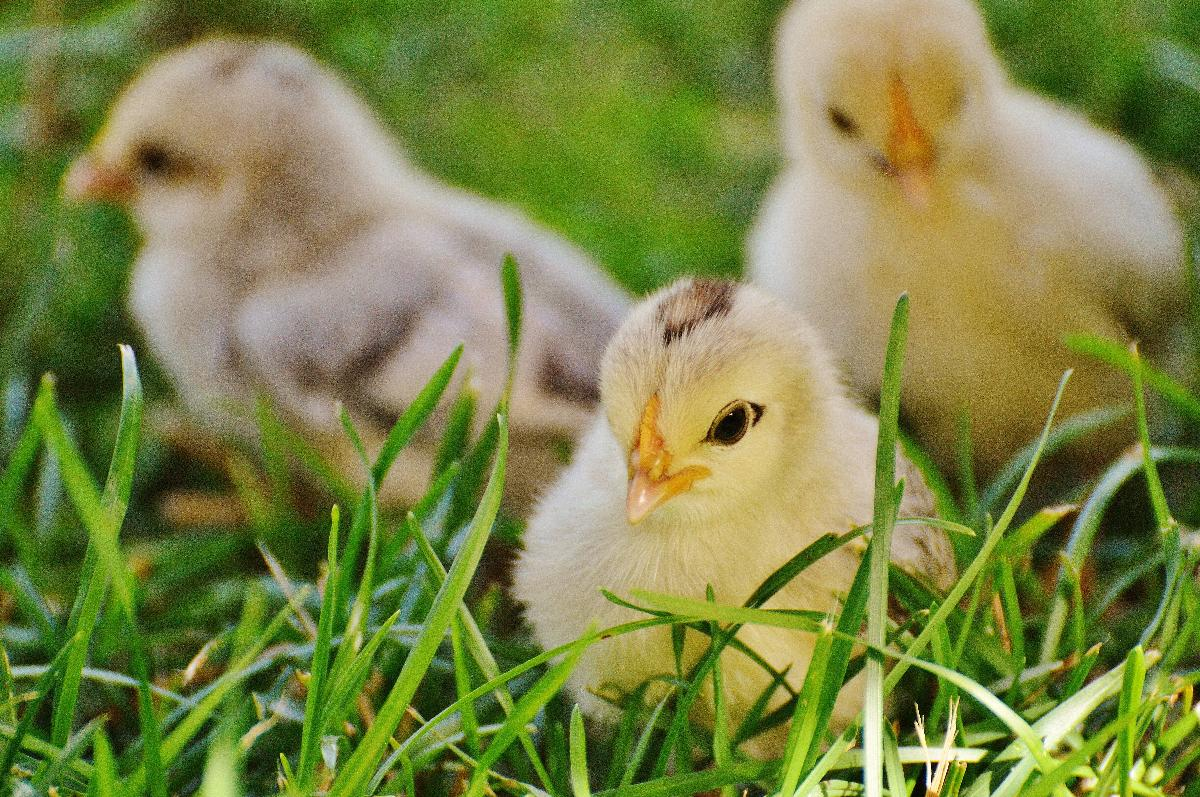

Egg incubation is tricky business. To incubate a chicken egg you have to keep it at *just* the right temperature. One way to do this would be to constantly check the temperature and turn up or down the incubator heaters manually. This might work but you'd have to do that for almost a month straight! A much better way would be to automate the temperature control by having a computer check and adjust the temperatures. That is exactly what the Temperature Control Lab can do! The lab comes equipped with two heaters and two thermometers so it can auto-adjust to keep the temperature just right. In this course we will learn about programming as we build a Java program that can maintain a perfect egg-incubation temperature.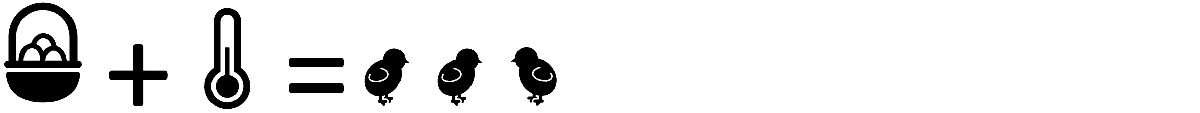

The final project of this course is to develop a temperature controller (like a thermostat) that could be used for an egg incubator. There are other factors such as humidity and turning the eggs that are important with incubators but we'll only focus on the temperature for this project.

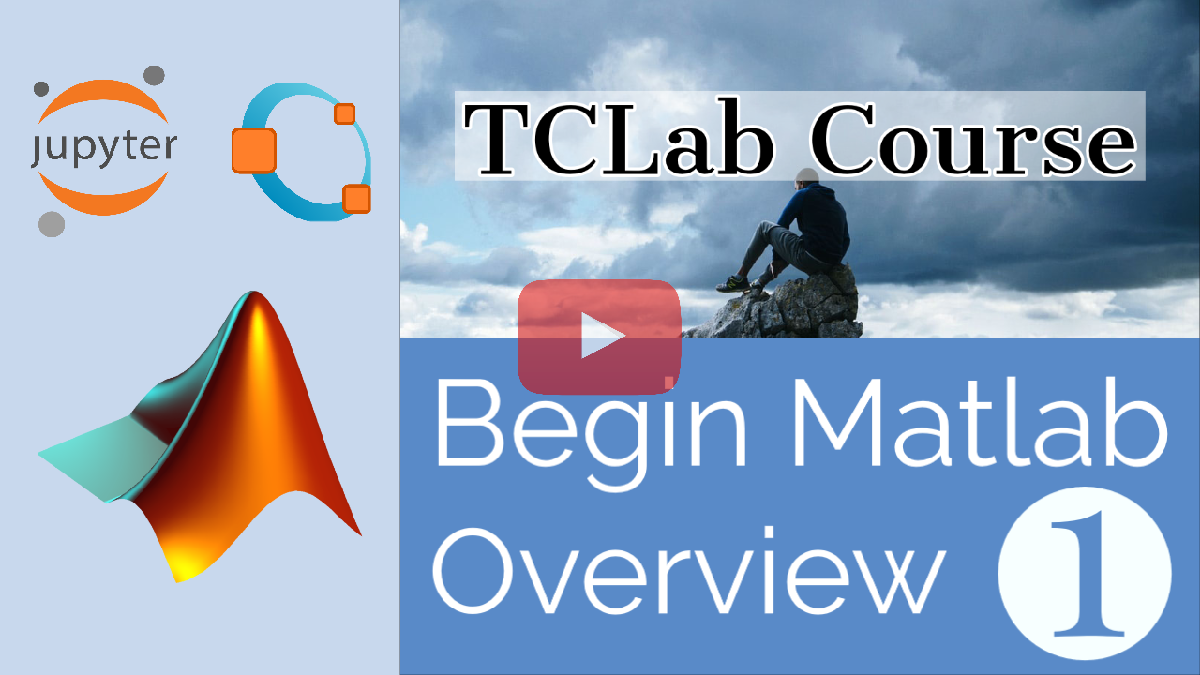

[Click here to watch the video: Matlab 👩‍💻 Course Overview](https://www.youtube.com/watch?v=VEKx_h84JL4&list=PLLBUgWXdTBDhJJnJW2q2G7e84MZM6dxRN)

## **Introduction**

Every programmer must have basic background knowledge before using the language in more complex projects. This tutorial steps through basic programming skills to build the more complex incubator temperature control. The introductory 12 exercises are designed to be completed in 2-3 hours (15-20 minutes each) but sections can be skipped if you already have the background knowledge.

If you want to do well in monitoring and controlling the egg temperature, you should work through the basic information. For those who already have experience with Matlab, this course also teaches the `tclab` Arduino functions.

- Overview (this lesson)

- Debugging

- Variables

- Printing

- Arduino

- Functions

- Loops

- Input

- If Statements

- Arrays

- Cell Arrays

- Plotting

It is best to follow the lessons in these steps because the later lessons build upon each other.

## **Install TCLab Module and Test LED**

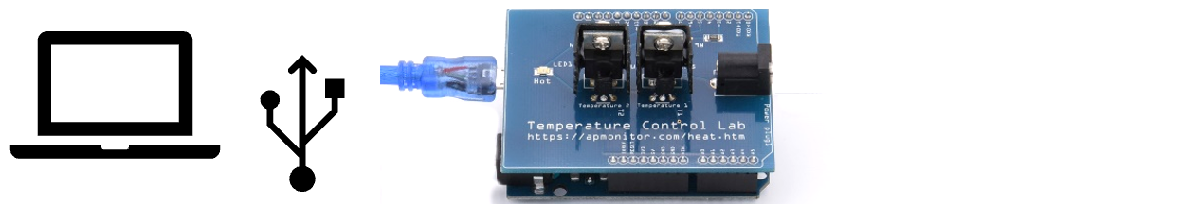

You need the TCLab to do the exercises. As a first step, plug in the TCLab (USB blue cable only) and download the `tclab.m` package by running the cell below (`Ctrl+Enter`). The `tclab.m` file will appear in the same folder where you are running `01. Overview.ipynb`. The source file `tclab.m` is from the [URL on GitHub](https://github.com/APMonitor/begin_matlab/blob/master/tclab.m) and may already be in your run directory. Matlab and Octave have different methods (`websave` or `urlwrite`) to retrieve an Internet file. We first `try` the Match function and then `catch` any errors by trying the Octave function.

file = 'tclab.m';
url = 'https://raw.githubusercontent.com/APMonitor/begin_matlab/master/tclab.m';

try
    % for MATLAB
    websave(file,url);
catch
    % for Octave
    urlwrite(url,file);
end

Run the following cell to turn on the TCLab LED for 5 seconds and verify that the install is working correctly. Type `Ctrl-Enter` to run the cell. The `clear all` removes all variables from the current session and disconnects any other Arduino connections.

clear all
lab = tclab;
lab.LED(100); disp('LED on')
pause(5.0);   disp('Paused 5 seconds')
lab.LED(0);   disp('LED off')
clear lab

There are additional Jupyter notebook files to help with TCLab installation and functions. There are also [Frequently Asked Questions](https://apmonitor.com/pdc/index.php/Main/ArduinoSetup) for setup and troubleshooting. More information on installation of TCLab package is in **5. Arduino** and also in the Jupyter notebook **TCLab Help**.